# Ex07. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Plot 2*2 Figures to visualize Laplace Transform

This assignment involves plotting the x(t) graph derived from the given math problem, visualizing the s-plane of the Laplace transform using abs(), real(), and imag() functions, and identifying the coordinates of poles and zeros. For the numerical computation, time $t$ is sampled at intervals of 0.01 from -5 to 5. Similarly, σ and the angular frequency ω both range from -5 to 5 with an increment of 0.05.

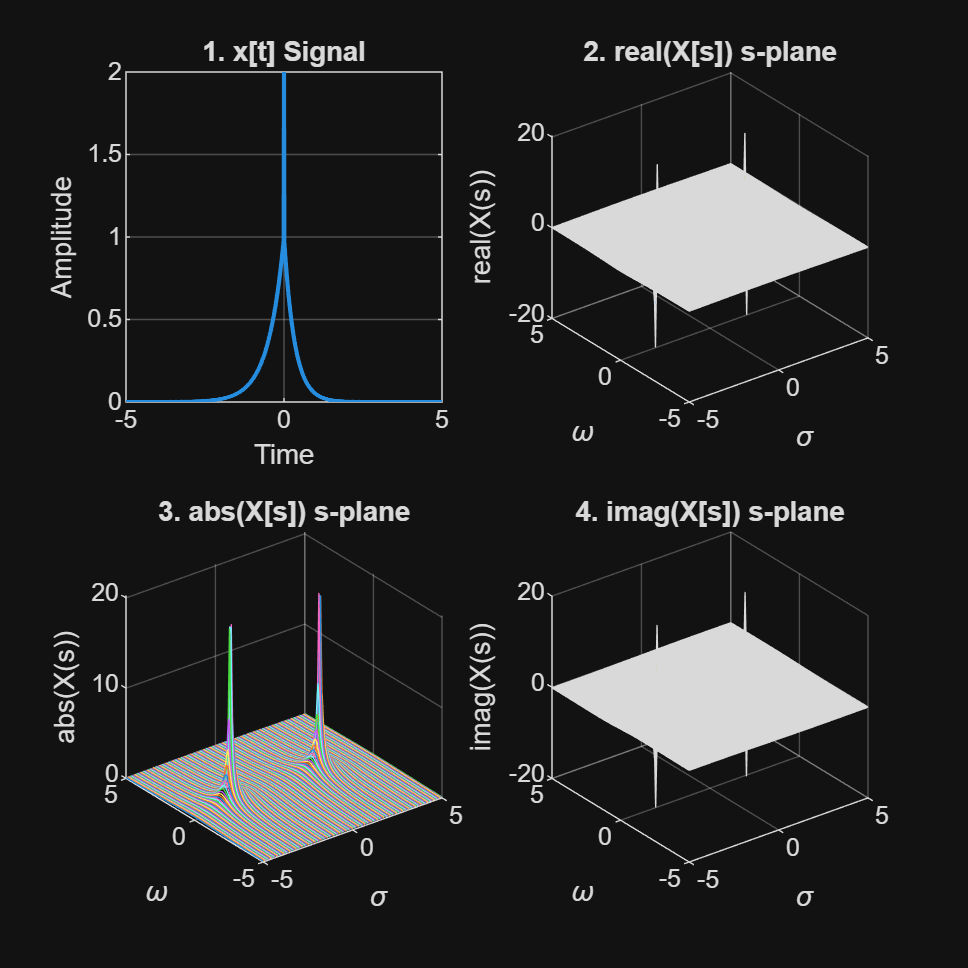

t = -5:0.01:5;
sigma = -5:0.05:5;
omega = -5:0.05:5;

[SIGMA, OMEGA] = meshgrid(sigma, omega);
s = SIGMA + 1j*OMEGA;

num = -5;
den = [1 1 -6];

x = @(t)exp(-3*t).*(t >= 0) + exp(2*t).*(t <= 0);
X = @(s) -5 ./ ((s + 3) .* (s - 2));


figure('Position', [100, 100, 800, 800]);

subplot(2, 2, 1);
    p1 = plot(t, x(t), 'LineWidth', 1.5);
    title('1. x[t] Signal');
    xlabel("Time");
    ylabel("Amplitude");
    grid on;
subplot(2, 2, 2);
    p2 = surf(SIGMA, OMEGA, real(X(s)));
    title('2. real(X[s]) s-plane');
    xlabel('\sigma');
    ylabel('\omega');
    zlabel('real(X(s))');
    grid on;
subplot(2, 2, 3);
    p3 = plot3(SIGMA, OMEGA, abs(X(s)));
    title('3. abs(X[s]) s-plane');
    xlabel('\sigma');
    ylabel('\omega');
    zlabel('abs(X(s))');
    grid on;
subplot(2, 2, 4);
    p4 = surf(SIGMA, OMEGA, imag(X(s)));
    title('4. imag(X[s]) s-plane');
    xlabel('\sigma');
    ylabel('\omega');
    zlabel('imag(X(s))');
    grid on;

 
poles_coords = roots(den);
zeros_coords = roots(num);

disp('--- Task 5: Coordinates of poles and zeros ---');

--- Task 5: Coordinates of poles and zeros ---


disp('Poles on s-plane:');

Poles on s-plane:


disp(poles_coords);

    -3
     2




disp('Zeros on s-plane:');

Zeros on s-plane:


if isempty(zeros_coords)
    disp('None');
else
    disp(zeros_coords);
end

None


%Since the numerator is a nonzero constant, there are no finite zeros

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.